# Actividad 1.10 (SLAM de Lidar) Ejemplo 1

Trayectoria 1

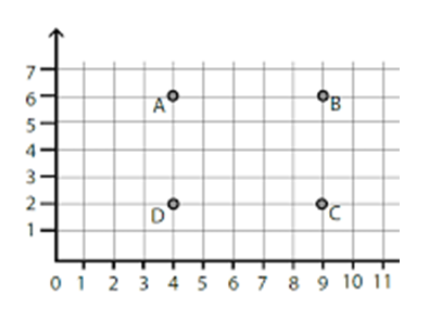

Para la primera trayectoria y este primer caso se realizó con el mapa de “exampleMap”, el robot sólo debía recorrer un cuadrado, para que la ruta fuera completamente líneas rectas, disminuir el rango de detección de obstáculos, debido a que en este ejercicio no se necesito ser tan estricto, de igual manera modifique variables como la velocidad angular para que fuera más rápida y la velocidad lineal la reduje.

En cuanto al segundo caso donde se usó el mapa de “complexMap”, debido a esto el robot viajaba completamente horizontal o vertical y a causa de esto y de que la evasión de obstáculos es con Bug 0, cuando el robot partía del primer punto al segundo punto que se encontraba justo enfrente, el robot se encontraba con un obstáculo que estaba perpendicular, lo que hacía que el robot solo diera vueltas ahí mismo y se ciclaba, por lo que opte por poner otros waypoints para evitar que se ciclara.

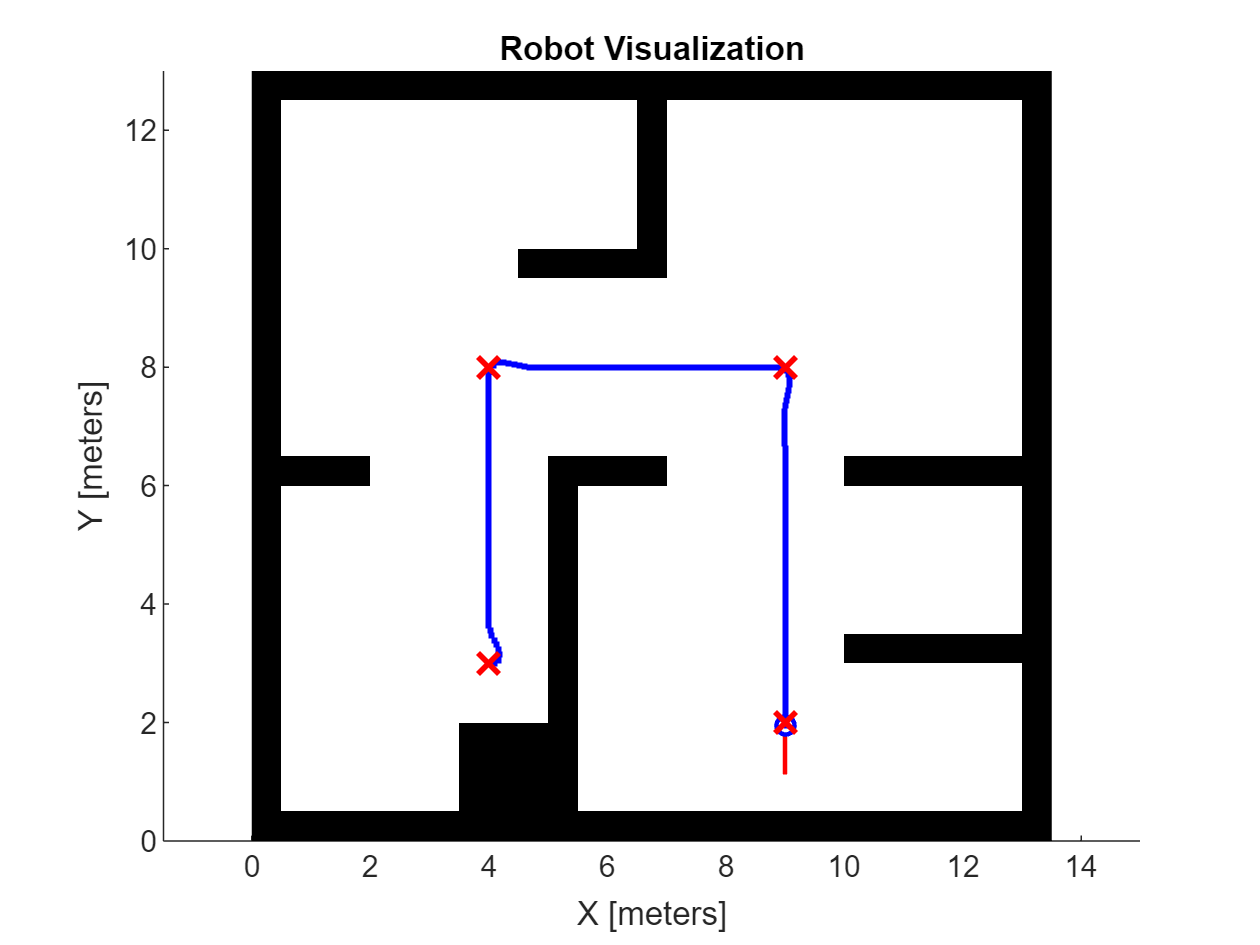

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:18;        % Time array

% Initial conditions
initPose = [4;3;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51%%%
lidar.maxRange = 0.5;%5%%%

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(4:3)';
             4 3;
             4 8;
             9 8;
             9 2;];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.3;%0.5
controller.DesiredLinearVelocity = 0.9; %0.75
controller.MaxAngularVelocity = 50;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

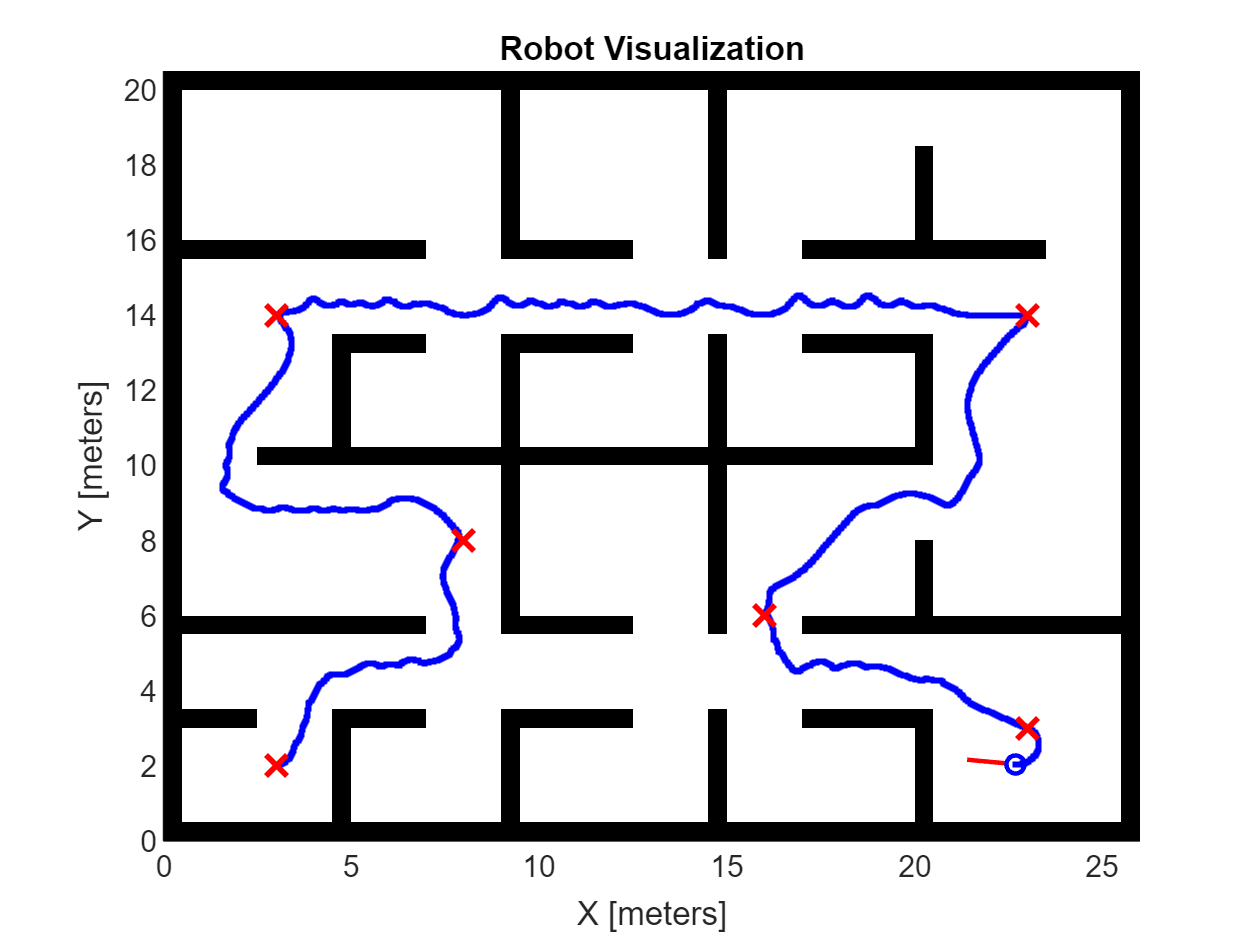

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:110;        % Time array

% Initial conditions
initPose = [3;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

load complexMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-2/4*pi,2/4*pi,500);%51%%%
lidar.maxRange = 1.5;%5%%%

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(3:2)';
             3 2;
             8 8;
             3 14;
             23 14;
             16 6;
             23 3;];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.3;%0.5
controller.DesiredLinearVelocity = 0.6; %0.75
controller.MaxAngularVelocity = 100;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 7]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [10 20]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end